# Volume Annotation App

## Load in data

s2 = load('mristack.mat');

% Place data into a VolumeModel
volModel = wt.model.VolumeModel;
volModel.ImageData = s2.mristack;

% Provide the world coordinates from edge to edge
volModel.WorldExtent = [
    0 300 % Y dimension in mm
    0 300 % X dimension in mm
    0 150 % Z dimension in mm
    ];

## Create the app

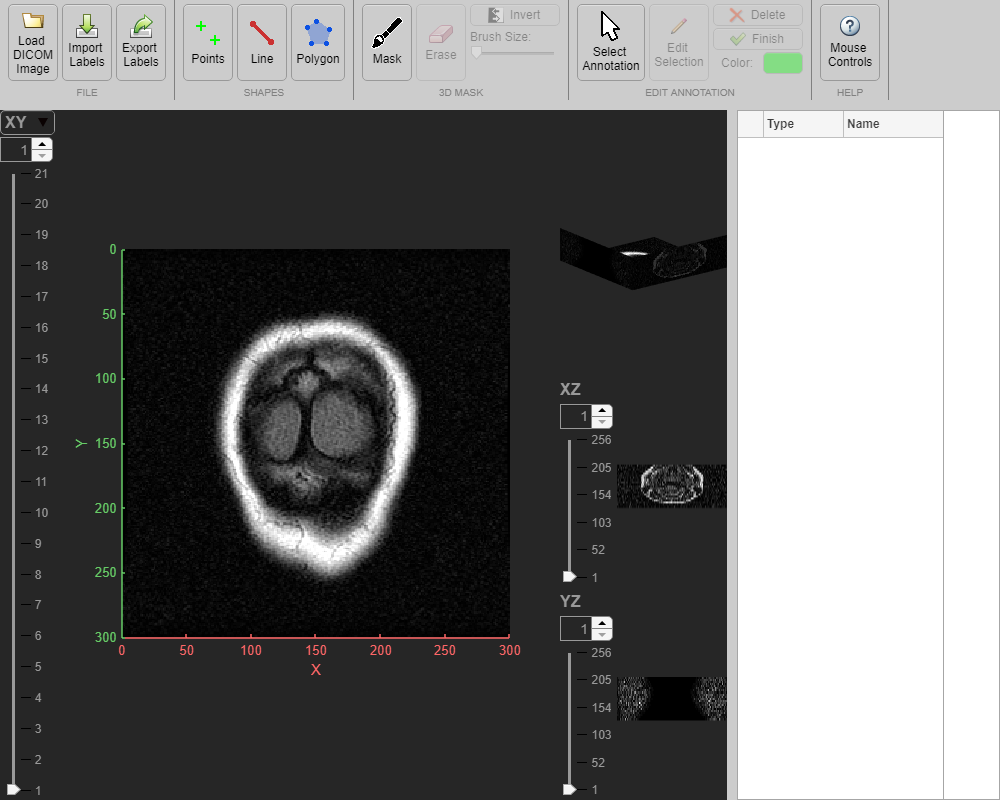

app = wt.apps.VolumeAnnotationApp('VolumeModel',volModel);

% Takes a few seconds to render - let finish before snapshot
drawnow

## Add Starting Annotations

This is just for show, to make the screenshot of the app in action

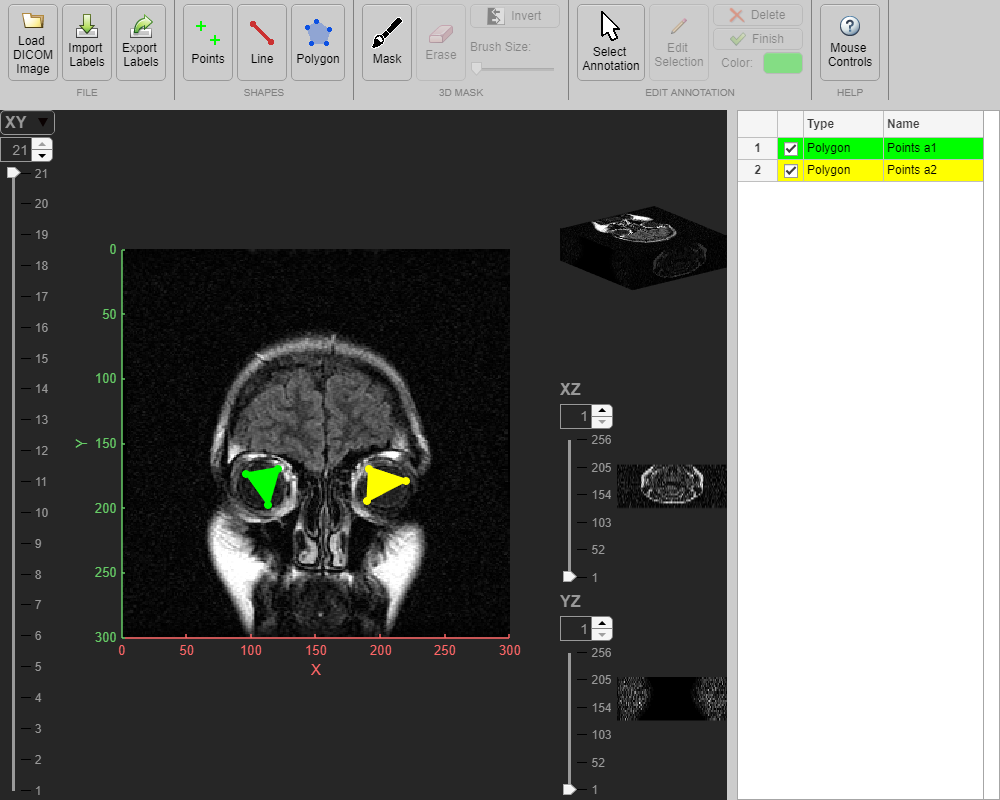

app.AnnotationViewer.Slice = 21;

thisPoints = [
  173.7510   96.2490  146.4285
  169.3740  121.2510  146.4285
  197.4990  113.1240  146.4285
    ];

a1 = wt.model.PolygonAnnotation(...
    'Name','Points a1',...
    'Points',thisPoints,...
    'Color',[0 1 0]);

thisPoints = [
  169.3740  191.2500  146.4285
  178.7490  219.9990  146.4285
  194.3760  189.9990  146.4285
    ];

a2 = wt.model.PolygonAnnotation(...
    'Name','Points a2',...
    'Points',thisPoints,...
    'Color',[1 1 0]);

app.AnnotationViewer.addAnnotation(a1);
app.AnnotationViewer.addAnnotation(a2);

% Takes a few seconds to render - let finish before snapshot
drawnow

*Copyright 2018-2020 The MathWorks, Inc.*